Q1

x=(4/3 -1)*3

x =    1.000000000000000


y=5*((1+exp(-50))-1)/((1+exp(-50))-1)

y =    NaN


z=log(exp(750))/100

z =    Inf


Q2

eps

ans =      2.220446049250313e-16


u=eps/2

u =      1.110223024625157e-16


x=2;
while x>1
    x=x/2;
end
disp(x)

     1



x=2;
while 1+x>1
    x=x/2;
end
disp(x)

     1.110223024625157e-16



Q3

beta=10;
t=8;
emin=-99;
emax=99;
x=0.23371258*10^(-4);
y=0.33678429*10^(2);
z=-0.33677811*10^(2);
fl=@(x) round(x,8,'significant');
disp(fl(x+fl(y+z)))

     6.413712600000000e-04



disp(fl(fl(x+y)+z))

     6.410000000000000e-04



disp(x+y+z)

     6.413712579984576e-04



disp(x+y+z-fl(x+fl(y+z)))

    -2.001542378018972e-12



disp(x+y+z-fl(fl(x+y)+z))

     3.712579984576541e-07



Q4

1782^12 + 1841^12

ans =      2.541210258614589e+39


1922^12

ans =      2.541210259314801e+39


format short
(1782^12 + 1841^12)^(1/12)

ans = 1.9220e+03

format long
(1782^12 + 1841^12)^(1/12)

ans =      1.921999999955867e+03


abs(1782^12 + 1841^12 -1922^12)

ans =      7.002119503409775e+29


3987^12 + 4365^12

ans =      6.397665634969862e+43


4472^12

ans =      6.397665634848672e+43


Q5

a=1;
b=-(10^7 +10^(-7));
c=1;
[x1,x2]=quadroot1(a,b,c)

x1 =     10000000


x2 =      9.965151548385620e-08


disp(x1)

    10000000



disp(x2)

     9.965151548385620e-08



[x1,x2]=quadroot2(a,b,c)

x1 =     10000000


x2 =      1.000000000000000e-07


disp(x1)

    10000000



disp(x2)

     1.000000000000000e-07



Q6

for x=[pi/2,11*pi/2,21*pi/2,31*pi/2]
    [s,n,m]=powersin(x)
    disp(s)
    disp(n)
    disp(m)
end

s =    1.000000000000000


n =     23


m =    1.570796326794897


   1.000000000000000



    23



   1.570796326794897



s =   -1.000000000212873


n =     75


m =      3.066514637383812e+06


  -1.000000000212873



    75



     3.066514637383812e+06



s =    0.999866764041849


n =    121


m =      1.467259672825497e+13


   0.999866764041849



   121



     1.467259672825497e+13



s =     -5.822018527024010e+03


n =    157


m =      7.988994169819993e+19


    -5.822018527024010e+03



   157



     7.988994169819993e+19



Q8

for n=1:16
    disp(fx(10^(-n)))
end

   1.051709180756477

   1.005016708416795

   1.000500166708385

   1.000050001667141

   1.000005000006965

   1.000000499962184

   1.000000049433680

   0.999999993922529

   1.000000082740371

   1.000000082740371

   1.000000082740371

   1.000088900582341

   0.999200722162641

   0.999200722162641

   1.110223024625157

     0



for n=1:16
    f=(exp(10^(-n))-1)/log(exp(10^(-n)));
    disp(f)
end

   1.051709180756476

   1.005016708416806

   1.000500166708342

   1.000050001666708

   1.000005000016667

   1.000000500000167

   1.000000050000002

   1.000000005000000

   1.000000000500000

   1.000000000050000

   1.000000000005000

   1.000000000000500

   1.000000000000050

   1.000000000000005

   1.000000000000000

   NaN



Q9

x0=11/2;
x1=61/11;
for i=1:32
    next=recurrence(x0,x1);
    x0=x1;
    x1=next;
end
disp(x1)

   100



Q10

p=1;
x=10^(-p);
while x>0
    a=(tan(x)-x)/x^3;
    b=(exp(x)+cos(x)-sin(x)-2)/x^3;
    p=p+1;
    x=10^(-p);
end
disp(a)

   NaN



disp(b)

   NaN



Q11

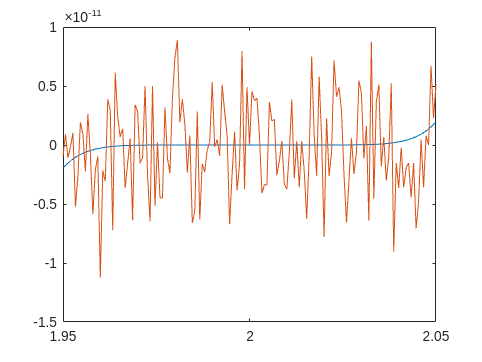

p1=@(x) (x-2).^9;
p2=[1 -18 144 -672 2016 -4032 5376 -4608 2304 -512];
interval=linspace(1.95,2.05,151);
value1=p1(interval);
value2=polyval(p2,interval);
plot(interval,value1);
hold on
plot(interval,value2);

function [x1, x2] = quadroot1( a, b, c)
d = sqrt( b^ 2 - 4 * a* c );
x1 = (-b + d) / (2*a);
x2 = (-b - d) / (2*a);
end

function [x1, x2] = quadroot2(a, b, c)
d = sqrt( b^ 2 - 4 * a* c );
x1 = (-b - sign(b) * d) / (2*a);
x2 = c/( a * x1 );
end

function[s,n,m] = powersin(x)
s = 0;
t = x;
n = 1;
m=x;
while s + t ~= s
s = s + t;
t = -x.^2/((n+1)*(n+2)).*t;
n = n + 2;
m=max(m,t);
end
end

function f=fx(x)
f=(exp(x)-1)/x;
end

function xkplus_1=recurrence(xk_1,xk)
xkplus_1=111-(1130-3000/xk_1)/xk;
end